# Note 2

Balance, velocity and position of REGBOT

A livescript copy of "regbot_mg.m" by group 16

Chapters

A: Balance controller (line 45)

B Velocity controller (line 115)

C Position controller (line 160)

close all
clc
clear
model='regbot_1mg_full'; %Simulink model name

## Parameters for REGBOT

### Motor

RA=3.3/2;       % Resistance of 2 motors in ohm
JA=1.3e-6*2;    % Motor inertia
LA=6.6e-3/2;    % Inductance of 2 motors
BA=3e-6*2;      % Rotor friction
Kemf=0.0105;    % Motor constant
Km=Kemf;

### Vehicle

NG=9.69;    % Gearing
WR=0.03;    % Wheel radius
BW=0.155;   % Wheel distance

### Modelling of parts in simulink

mmotor=0.193;                           % Total mass of motor and gear in Kg
mframe=0.32;                            % Total mass of frame and base print in Kg
mtopextra=0.97-mframe-mmotor;           % Extra mass on top (charger and battery) in Kg
mpdist=0.10;                            % Distance to lid in M
pushDist=0.1;                           % Vertical position relative to motor axle

## Wheel velocity controller (no balance) PI regulator

### Making controller to transfer function found on day 5. The function 'Controller' is from the file 'Controller.m'.

Gwv = minreal(tf([0, (1.225+2.119)/2], [1, (5.535+9.582)/2]));
%figure()
%bode(Gwv)
%grid on

[G_olwv, Kpwv, tiwv, tdwv] = Controller(Gwv, 2, 0, 90, 0);

Crossover frequency at: -63.4349° phase.
Please check if omega_c of 15.1905 rad/s is reasonable...


Kpwv

Kpwv = 9.0765

tiwv

tiwv = 0.1317

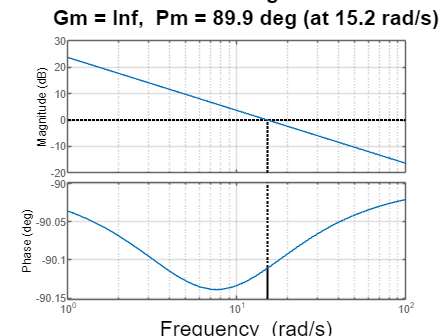

figure()
margin(G_olwv)
grid on

G_clwv = G_olwv/(1+G_olwv);
stepinfo(G_clwv)

ans = struct with fields:
         RiseTime: 0.1441
    TransientTime: 0.2552
     SettlingTime: 0.2552
      SettlingMin: 0.9021
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 0.4544


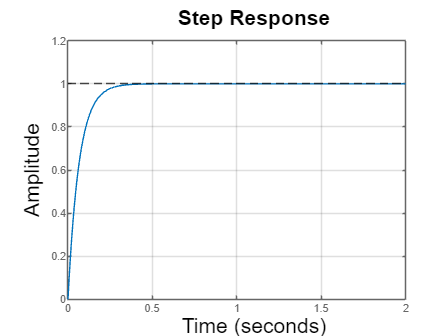

figure()
step(G_clwv, 2)
grid on
hold on
yline(1, '--k')
hold off

% THESE WERE THE SAMPLE VALUES !!
%Kpwv = 15;        % Kp
%tiwv = 0.05;      % Tau_i

Kffwv = 0;        % feed forward constant
startAngle = 3;   % tilt in degrees at time zero % Implemented in simulink inside big block "robot with balance"
twvlp = 0.005;    % Simulinks velocity noise low pass filter time constant (recommended)

## A: Balance controller

### Transfer function from velocity reference to tilt angle (balance controller)

#### Motor velocity reference to tilt angle

% iosTV(1) = linio(strcat(model,'/vel_ref'),1,'openinput');
% iosTV(2) = linio(strcat(model, '/tilt_angle'),1,'openoutput');
% setlinio(model,iosTV);
% opTV = [0];                           % Use snapshot time(s) 0 seconds
% sysTV = linearize(model,iosTV,opTV);  % Linearize the model
% [numTV,denTV] = ss2tf(sysTV.A, sysTV.B, sysTV.C, sysTV.D);
% Gtv = minreal(tf(numTV, denTV))                      % Simplifies transfer function

% I've manually typed the transfer function because all parameters
% otherwise need to be defined in the simulink file. 
Gtv = tf([0,0,0,-3.771e05, -4.885e08, -8.573e10, -6.233e11, -1.85e09], [1, 2453, 1.341e06, 1.981e08, 9.219e09, 1.538e10, -7.107e11, -3.814e12])

Gtv =
 
                   -377100 s^4 - 4.885e08 s^3 - 8.573e10 s^2 - 6.233e11 s - 1.85e09
  --------------------------------------------------------------------------------------------------
  s^7 + 2453 s^6 + 1.341e06 s^5 + 1.981e08 s^4 + 9.219e09 s^3 + 1.538e10 s^2 - 7.107e11 s - 3.814e12
 
Continuous-time transfer function.



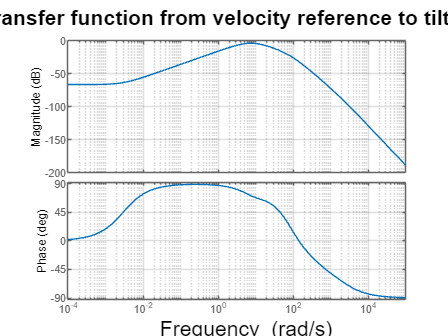

bode(Gtv)
grid on
title('Transfer function from velocity reference to tilt angle')

pole(Gtv)

ans = 1.0e+03 *

  -1.7495 + 0.0000i
  -0.5062 + 0.0000i
  -0.0969 + 0.0193i
  -0.0969 - 0.0193i
   0.0093 + 0.0000i
  -0.0064 + 0.0025i
  -0.0064 - 0.0025i


One RHP pole

### AB: Post integrator for stability

Calculating the parameters for a post integrator as the first layer - right before the velocity controller.

s = tf('s');
[mag,phase,wout] = bode(Gtv);
mag=mag2db(squeeze(mag)); phase=squeeze(phase); wout=squeeze(wout);

As can be seen on the bode-plot of Gtv in the above section, there is no point where the magnitude crosses 0 or the phase crosses -180. Instead, we find the "crossover"-frequency as the peak of the magnitude-plot.

mmax = max(mag)

mmax = -3.6857

omega_post=interp1(mag,wout,mmax,'linear')

omega_post = 7.2392

w_post=interp1(phase,wout,mmax,'linear')

w_post = 155.3968

tau_post = 1/omega_post

tau_post = 0.1381

CPIpost = (tau_post*s+1)/(tau_post*s)

CPIpost =
 
  0.1381 s + 1
  ------------
    0.1381 s
 
Continuous-time transfer function.



### AC: Stability check

Checking the stability of the system added with a post integrator:

Gtv_post = -Gtv*CPIpost;
pole(Gtv_post)

ans = 1.0e+03 *

   0.0000 + 0.0000i
  -1.7495 + 0.0000i
  -0.5062 + 0.0000i
  -0.0969 + 0.0193i
  -0.0969 - 0.0193i
   0.0093 + 0.0000i
  -0.0064 + 0.0025i
  -0.0064 - 0.0025i


We can see the addition of a pole at 0, which is from the post-integrator above

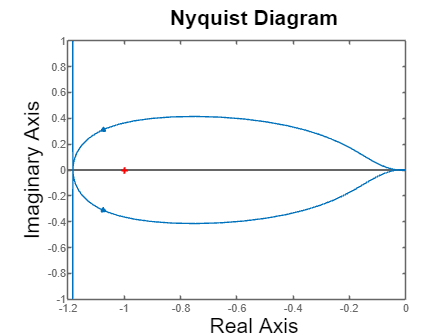

figure()
nyquist(Gtv_post)
hold on
ylim([-1,1])

%exportgraphics(gcf, '/Users/bertelfalkow/Desktop/postnyquist.png', 'Resolution', 300);

Conclusion: One right hand plane pole, but there is also one encirclement to compensate.

### AD: Comparison of the two bodeplots

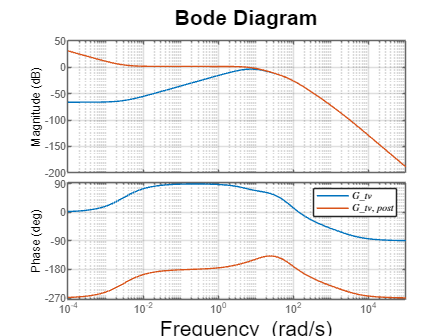

figure()
bode(Gtv)
hold on
bode(Gtv_post)
l = legend('$W_{p1}$', '$W_{p2}$', 'Interpreter', 'latex');
set(l, 'string',{'$G_{tv}$', '$G_{tv,post}$'})
grid on
hold off

## AE: Implementing balance controller 

N_i = 10;
alpha = 0.02;
gamma_m = 60;
G = Gtv_post;
phaseG=rad2deg(deg2rad(gamma_m)-asin((1-alpha)/(1+alpha))-pi+atan(1/N_i));
disp("Crossover frequency at: "+phaseG+"° phase.")

Crossover frequency at: -188.1905° phase.


interval = 90;
[mag,phase,w]=bode(G);
phase=squeeze(phase); w=squeeze(w);
omega_c=interp1(phase(interval:end),w(interval:end),phaseG,'linear');
disp(omega_c)

  167.2920



tau_i=N_i*(1/omega_c);
tau_d=(1)/(omega_c*sqrt(alpha));
C_pi=tf([tau_i,1],[tau_i,0]);
C_D=tf([tau_d,1],[alpha*tau_d,1]);
Kp=1/(abs(freqresp((G*C_D*C_pi),1j*omega_c)));
G_ol=minreal(G*C_D*C_pi*Kp);
K_PTV = Kp

K_PTV = 7.5876

tau_iTV = tau_i

tau_iTV = 0.0598

tau_dTV = tau_d

tau_dTV = 0.0423

alphaTV = alpha

alphaTV = 0.0200

G_olTV = G_ol;

C_piTV=tf([tau_iTV,1],[tau_iTV,0]);
C_DTV=tf([tau_dTV,1],[alphaTV*tau_dTV,1]);
G_clTV = minreal(Gtv_post*C_piTV*K_PTV/(1+(Gtv_post*C_DTV*C_piTV*K_PTV)));

Validating effect of controller

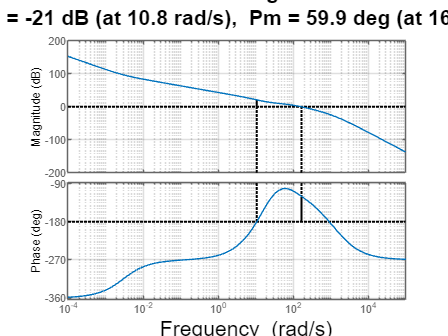

figure()
margin(G_olTV)
grid on

stepinfo(G_clTV)

ans = struct with fields:
         RiseTime: 0.0705
    TransientTime: 0.2287
     SettlingTime: 0.2287
      SettlingMin: 0.9006
      SettlingMax: 1.0362
        Overshoot: 3.6170
       Undershoot: 0
             Peak: 1.0362
         PeakTime: 0.1631


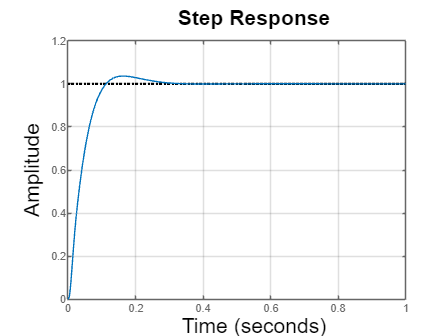

figure()
step(G_clTV, 1)
grid on

## B: Velocity controller

### Transfer function from tilt reference to velocity (Velocity controller)

#### Tilt reference to robot velocity

% iosRT(1) = linio(strcat(model,'/theta_ref'),1,'openinput');
% iosRT(2) = linio(strcat(model, '/vel'),1,'openoutput');
% setlinio(model,iosRT);
% opRT = [0];                           % Use snapshot time(s) 0 seconds
% sysRT = linearize(model,iosRT,opRT);  % Linearize the model
% [numRT,denRT] = ss2tf(sysRT.A, sysRT.B, sysRT.C, sysRT.D);
% Grt = minreal(tf(numRT, denRT))                      % Simplifies transfer function
Grt = minreal(tf([0,0, -2.54e05, -2.578e08, -3.778e09, 5.131e09, 2.837e11, 1.063e12, 6.257e10], [1, 2253, 1.012e06, 1.494e08, 4.948e09, 5.28e10, 1.743e11, 1.074e10, 3.035e07]))

Grt =
 
          -254000 s^6 - 2.578e08 s^5 - 3.778e09 s^4 + 5.131e09 s^3 + 2.837e11 s^2 + 1.063e12 s + 6.257e10
  ----------------------------------------------------------------------------------------------------------------
  s^8 + 2253 s^7 + 1.012e06 s^6 + 1.494e08 s^5 + 4.948e09 s^4 + 5.28e10 s^3 + 1.743e11 s^2 + 1.074e10 s + 3.035e07
 
Continuous-time transfer function.



Checking transfer function properties

pole(Grt)

ans = 1.0e+03 *

  -1.7118 + 0.0000i
  -0.2502 + 0.0462i
  -0.2502 - 0.0462i
  -0.0244 + 0.0000i
  -0.0099 + 0.0000i
  -0.0064 + 0.0000i
  -0.0001 + 0.0000i
  -0.0000 + 0.0000i


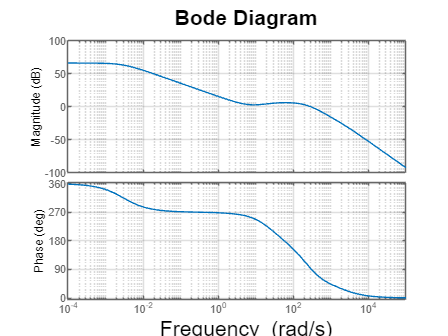

figure()
bode(Grt)
grid()

### BB: Pre-filter to reduce peak

To reduce the peak found at around 100 rad/s

[mag,phase,wout] = bode(Grt);
mag=mag2db(squeeze(mag)); phase=squeeze(phase); wout=squeeze(wout);

As can be seen on the bode-plot of Gtv in the above section, there is no point where the magnitude crosses 0 or the phase crosses -180. Instead, we find the "crossover"-frequency as the peak of the magnitude-plot.

mmax = min(mag(1:90))

mmax = 2.9635

omega_filter=interp1(mag(1:90),wout(1:90),mmax,'linear')

omega_filter = 9.7302

tau_filter = 1/omega_filter

tau_filter = 0.1028

CPF = (1)/(tau_filter*s+1)

CPF =
 
       1
  ------------
  0.1028 s + 1
 
Continuous-time transfer function.



Grt_filter = minreal(Grt*CPF);

Checking the effect of the filter

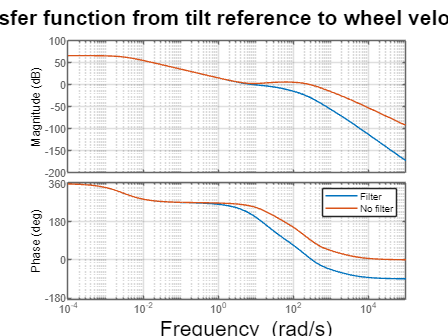

figure()
bode(Grt_filter)
hold on
bode(Grt)
grid on
title("Transfer function from tilt reference to wheel velocity filter")
legend(["Filter", "No filter"])
hold off

### BC: Implementing tilt controller

N_iRT=8;

alphaRT=0.5;

gamma_mRT=65;

N_iRT=5;
alphaRT=0.8;
gamma_mRT=65;
[G_olRT, K_PRT, tau_iRT, tau_dRT] = Controller(Grt_filter, N_iRT, alphaRT, gamma_mRT, 360);

Crossover frequency at: -110.0694° phase.
Please check if omega_c of 2.5736 rad/s is reasonable...


K_PRT

K_PRT = 0.3506

tau_iRT

tau_iRT = 1.9428

tau_dRT

tau_dRT = 0.4344

C_piRT=tf([tau_iRT,1],[tau_iRT,0]);
C_DRT=tf([tau_dRT,1],[alphaRT*tau_dRT,1]);
G_clRT = Grt_filter*C_piRT*K_PRT/(1+Grt_filter*C_piRT*K_PRT*C_DRT);

Validating effect of controller

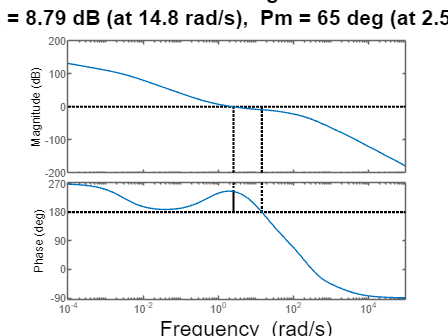

figure()
margin(G_olRT)

stepinfo(G_clRT)

ans = struct with fields:
         RiseTime: 0.5523
    TransientTime: 4.9947
     SettlingTime: 5.2288
      SettlingMin: 0.9043
      SettlingMax: 1.1159
        Overshoot: 11.5913
       Undershoot: 18.5977
             Peak: 1.1159
         PeakTime: 1.9641


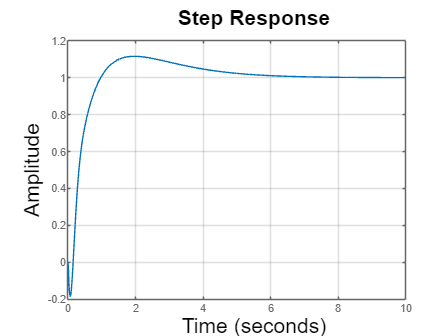

figure()
step(G_clRT)
grid on

## C: Position controller

### Finding transfer function  Transfer function from velocity reference to x_position (position controller)

#### Velocity reference to x_position

% iosXV(1) = linio(strcat(model,'/v_ref'),1,'openinput');
% iosXV(2) = linio(strcat(model, '/x_p'),1,'openoutput');
% setlinio(model,iosXV);
% opXV = [0];                           % Use snapshot time(s) 0 seconds
% sysXV = linearize(model,iosXV,opXV);  % Linearize the model
% [numXV,denXV] = ss2tf(sysXV.A, sysXV.B, sysXV.C, sysXV.D);
% Gxv = minreal(tf(numXV, denXV))                      % Simplifies transfer function
Gxv = tf([0,0,0,0, -8.672e05, -1.058e09, -1.94e11, -3.479e12, -8.938e12, 2.046e14, 1.703e15, 4.647e15, 4.267e15, 2.388e14], [1, 2465, 1.493e06, 3.759e08, 4.482e10, 1.386e12, 2.098e13, 1.817e14, 9.369e14, 2.878e15, 5.071e15, 4.288e15, 2.388e14, 0])

Gxv =
 
                       -867200 s^9 - 1.058e09 s^8 - 1.94e11 s^7 - 3.479e12 s^6 - 8.938e12 s^5 + 2.046e14 s^4 + 1.703e15 s^3 + 4.647e15 s^2 + 4.267e15 s + 2.388e14
  -------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  s^13 + 2465 s^12 + 1.493e06 s^11 + 3.759e08 s^10 + 4.482e10 s^9 + 1.386e12 s^8 + 2.098e13 s^7 + 1.817e14 s^6 + 9.369e14 s^5 + 2.878e15 s^4 + 5.071e15 s^3 + 4.288e15 s^2 + 2.388e14 s
 
Continuous-time transfer function.



Checking transfer function properties

pole(Gxv)

ans = 1.0e+03 *

   0.0000 + 0.0000i
  -1.7126 + 0.0000i
  -0.3756 + 0.0000i
  -0.1699 + 0.1447i
  -0.1699 - 0.1447i
  -0.0076 + 0.0057i
  -0.0076 - 0.0057i
  -0.0089 + 0.0000i
  -0.0046 + 0.0004i
  -0.0046 - 0.0004i


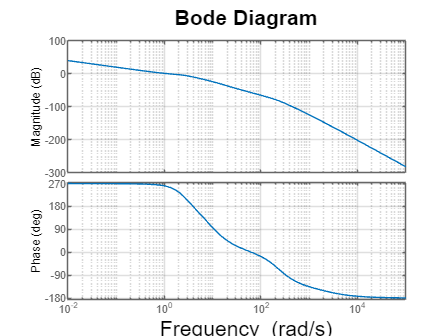

figure()
bode(Gxv)
grid on

### CB: Implementing position controller

N_iXV=2.5;

alphaXV=0.18;

gamma_mXV=60;

N_iXV=2;
alphaXV=0.05;
gamma_mXV=60;
% Have to shift everything by 360 degrees.
[G_olXV, K_PXV, tau_iXV, tau_dXV] = Controller(Gxv, N_iXV, alphaXV, gamma_mXV, 360);

Crossover frequency at: -158.2262° phase.
Please check if omega_c of 3.083 rad/s is reasonable...


K_PXV

K_PXV = 0.4237

tau_iXV

tau_iXV = 0.6487

tau_dXV

tau_dXV = 1.4506

C_piXV=tf([tau_iXV,1],[tau_iXV,0]);
C_DXV=tf([tau_dXV,1],[alphaXV*tau_dXV,1]);

G_clXV_fb = Gxv*C_piXV*K_PXV/(1+Gxv*C_piXV*K_PXV*C_DXV);
G_clXV_ff = Gxv*C_piXV*K_PXV*C_DXV/(1+Gxv*C_piXV*K_PXV*C_DXV);

Validating effect of controller

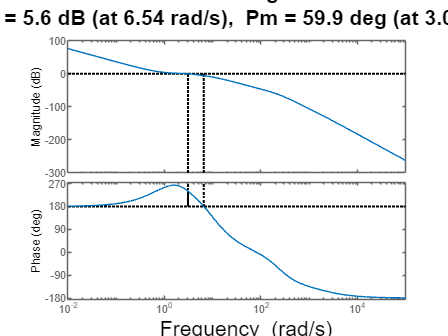

figure()
margin(G_olXV)

stepinfo(G_clXV)

ans = struct with fields:
         RiseTime: 2.4961
    TransientTime: 8.3574
     SettlingTime: 8.3708
      SettlingMin: 0.9002
      SettlingMax: 1.0623
        Overshoot: 6.2340
       Undershoot: 1.0290
             Peak: 1.0623
         PeakTime: 5.5337


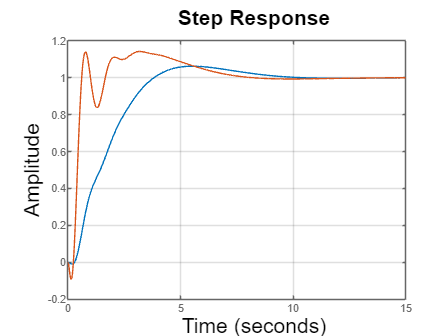

figure()
step(G_clXV_fb, 15)
hold on
step(G_clXV_ff,15)
grid on